%let each unit be 1cm
%trying to achieve forward kinematics: 
% the position of the tool tip in terms of the base reference frame 
% (gives the actual position) then can determine the desired tool tip 
% position (relative to the heart)

% HRF = heart reference frame
% VRF = fixed point where the voice coil actuator sits inside the device (non-actuating part)
% TRF = tool-tip reference frame (actuating)
% BRF = base of device

SETUP & INPUTS

% Define the plane
[X, Y] = meshgrid(0:40.2, 0:80.4);%should be 40.2 & 80.4
Z = zeros(size(X));% Z is constant for a flat plane

% Plot the plane
surf(X, Y, Z, 'FaceAlpha', 0.5);
hold on;

%%%%%%% INPUTS %%%%%%%%%%%
%potentiometer
d56potentiometer=2;
%gyro
theta2_yaw=(0)*pi/180;
theta3_pitch=(-45)*pi/180;
theta4_roll=(0)*pi/180;
% POI position, given from camera script (z value)
POI_pt=[20,60,10];

%fixed
%BRF_pt = [40.2-13.5, 21.0, 0];%40.2-13.5 x offset
BRF_pt = [20, 20, 0]

BRF_pt =     20    20     0


%fixed lengths
%l01A=26.1;d01=0;l01B=0;l45A=10.7;1;l45B=11.5;l56A=2;d56potentiometer=2;l56B=5;
%l01A=10.1;d01=0;l01B=0;l45A=2.7;1;l45B=2.5;l56A=1;d56potentiometer=1;l56B=1;
%%%%%%%%%%%%%%%%%%%%%%%%%%

Find the current tool tip position relative to the POI


% the euclidean distance between the tooltip and POI 
tooltipwrtPOI_pt=current_tooltip_pt(d56potentiometer,theta2_yaw,theta3_pitch,theta4_roll,BRF_pt,POI_pt)

T04 =     0.0000    1.0000    0.0000         0
    0.7071   -0.0000    0.7071         0
    0.7071    0.0000   -0.7071   26.1000
         0         0         0    1.0000


T05 =     0.0000    1.0000    0.0000    0.0000
    0.7071   -0.0000    0.7071    7.5660
    0.7071    0.0000   -0.7071   33.6660
         0         0         0    1.0000


T06 =     0.0000    1.0000    0.0000    0.0000
    0.7071   -0.0000    0.7071   15.6978
    0.7071    0.0000   -0.7071   25.5343
         0         0         0    1.0000


T07 =     0.0000    1.0000    0.0000    0.0000
    0.7071   -0.0000    0.7071   22.0617
    0.7071    0.0000   -0.7071   19.1704
         0         0         0    1.0000


tooltipwrtPOI_pt =     0.0000   62.0617   29.1704


lPOItotool=distance3D(tooltipwrtPOI_pt,POI_pt)

lPOItotool = 27.7804

Find the desired tooltip position

desiredoffsetfromPOI=10

desiredoffsetfromPOI = 10

unitfromPOI=unitVectorBetweenPoints(POI_pt,tooltipwrtPOI_pt)

unitfromPOI =    -0.7199    0.0742    0.6901


desiredtool_pt=POI_pt+desiredoffsetfromPOI*unitfromPOI;%multiply unit vector by constant to get a different desired point
% ltooltodesired=distance3D(tooltipwrtPOI_pt,desiredtool_pt)
ltooltodesired=lPOItotool-desiredoffsetfromPOI%subtract whatever distance to be maintained

ltooltodesired = 17.7804

PID

% PID controller parameters
%PID error is distance between desired and actual tooltip position
% Kp = 0.5;
% Ki = 0.1;
% Kd = 0.01;
% integral = 0;
% prev_error = 0;
% max_iterations = 100;
% tolerance = 1;
% 
% for i = 1:max_iterations
%     % Calculate current tooltip position
%     [T04,T05,T06,T07] = jointstoBRF(d56potentiometer, theta2_yaw, theta3_pitch, theta4_roll);
%     current_tooltip = BRF_pt + [T07(1,4), T07(2,4), T07(3,4)];
%     
%     % Calculate error
%     error = distance3D(current_tooltip, desiredtool_pt);
%     
%     % PID control
%     integral = integral + error;
%     derivative = error - prev_error;
%     adjustment = Kp*error + Ki*integral + Kd*derivative;
%     
%     % Update d56potentiometer
%     d56potentiometer = d56potentiometer + adjustment;
%     
%     % Check if within tolerance
%     if abs(error) < tolerance
%         break;
%     end
%     
%     prev_error = error;
% end
% 
% %Final d56potentiometer length
% d56potentiometer
% 
% % Final distance to desired position
% error
% 
% % Recalculate final position
% % [T04,T05,T06,T07] = jointstoBRF(d56potentiometer, theta2_yaw, theta3_pitch, theta4_roll);

PLOT points for robot

[T04,T05,T06,T07] = jointstoBRF(d56potentiometer, theta2_yaw, theta3_pitch, theta4_roll);
plotrobot(BRF_pt,POI_pt,T04,T05,T06,T07)

display

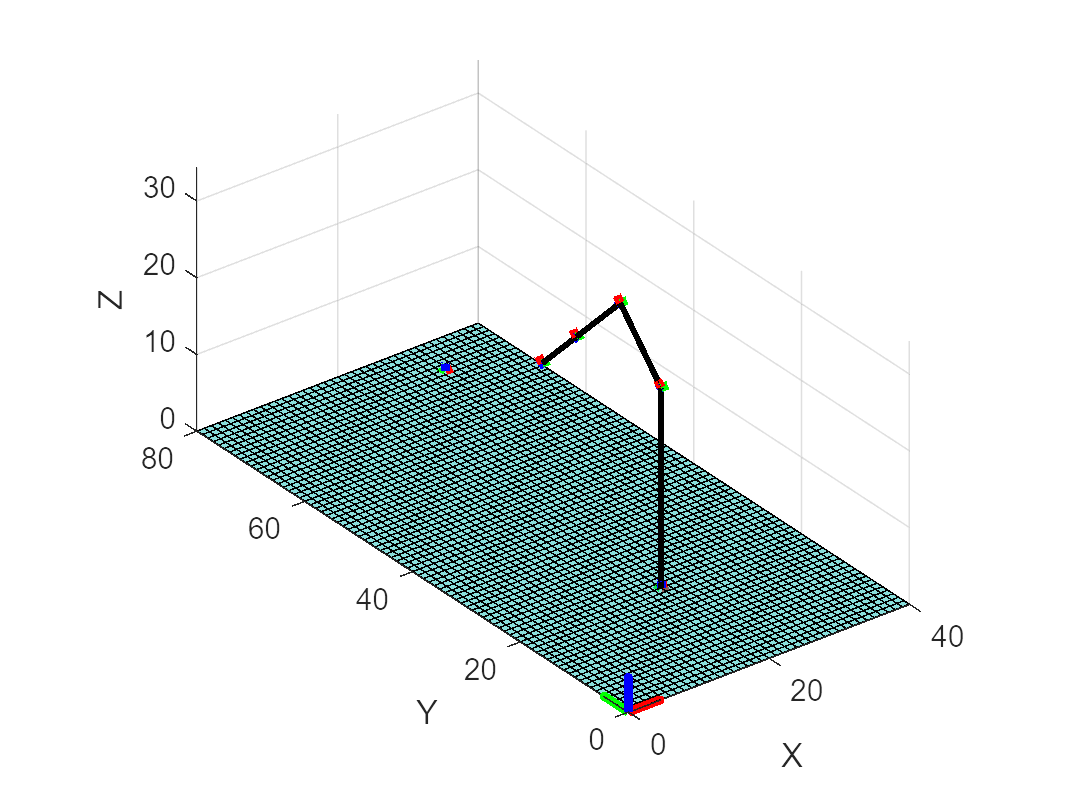

% Set axis properties
axis equal;
xlabel('X');
ylabel('Y');
zlabel('Z');
view(3);

functions 

% JointTransformation(dhparams(i,1), dhparams(i,2), dhparams(i,3), dhparams(i,4));
function T = JointTransformation(a, alpha, d, theta)
    T = [cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha)  a*cos(theta)
         sin(theta) cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta)
         0          sin(alpha)            cos(alpha)             d
         0          0                     0                      1];
end


%joints in terms of BRF
function [T04,T05,T06,T07]=jointstoBRF(d56potentiometer,theta2_yaw,theta3_pitch,theta4_roll)
    l01A=26.1;d01=0;l01B=0;l45A=10.7;1;l45B=11.5;l56A=2;l56B=5;
    %           a       α       d                           θ
    dhparams = [0   	0	    l01A+d01+l01B               0
                0	    pi/2    0                           theta2_yaw+pi/2%so starting oritentation is towards +y
                0	    pi/2    0                           theta3_pitch+pi/2%so starting orientation is L shape
                0	    0       0                           theta4_roll
                l45A    0       0                           0
                0       0       l45B                        0
                0	    0	    l56A+d56potentiometer+l56B  0];
    
    %%%%% practice params %%%%%%
    % dhparams = [10 0 0  pi/2;
    %             10 0 0 -pi/2;
    %             10 0 0 -pi/2;];
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    
    T01= JointTransformation(dhparams(1,1), dhparams(1,2), dhparams(1,3), dhparams(1,4));
    T12= JointTransformation(dhparams(2,1), dhparams(2,2), dhparams(2,3), dhparams(2,4));
    T23= JointTransformation(dhparams(3,1), dhparams(3,2), dhparams(3,3), dhparams(3,4));
    T34= JointTransformation(dhparams(4,1), dhparams(4,2), dhparams(4,3), dhparams(4,4));
    T45= JointTransformation(dhparams(5,1), dhparams(5,2), dhparams(5,3), dhparams(5,4));
    T56= JointTransformation(dhparams(6,1), dhparams(6,2), dhparams(6,3), dhparams(6,4));
    T67= JointTransformation(dhparams(7,1), dhparams(7,2), dhparams(7,3), dhparams(7,4));

    T04=T01*T12*T23*T34;%gyro p3
    T05=T01*T12*T23*T34*T45;
    T06=T01*T12*T23*T34*T45*T56;
    T07=T01*T12*T23*T34*T45*T56*T67;%tool tip to base T07

end

%step 1 is to find tool tip wrt to BRF
%step 2 is to define a transformation matrix between BRF & POI
function tooltipwrtPOI_pt=current_tooltip_pt(d56potentiometer,theta2_yaw,theta3_pitch,theta4_roll,BRF_pt,POI_pt)

    %fixed lengths
    l01A=26.1;d01=0;l01B=0;l45A=10.7;1;l45B=11.5;l56A=2;l56B=5;
    
    %get wrist (joint4) to tooltip(joint7) in terms of the BRF
    [T04,T05,T06,T07]=jointstoBRF(d56potentiometer,theta2_yaw, theta3_pitch, theta4_roll)
    
    %define transformation matrix between BRF and POI
    %Transform tooltip in terms of POI
    TBRFPOI=[1 0 0 POI_pt(1)-BRF_pt(1);
     0 1 0 POI_pt(2)-BRF_pt(2);
     0 0 1 POI_pt(3)-BRF_pt(3);
     0 0 0 1];
    tooltipwrtPOI_pt=(TBRFPOI*[T07(1,4);T07(2,4);T07(3,4);1])'; %take transpose (row vector)
    tooltipwrtPOI_pt=[tooltipwrtPOI_pt(1) tooltipwrtPOI_pt(2) tooltipwrtPOI_pt(3)] ;
    %tooltipwrtBRF_pt=[T07(1,4) T07(2,4) T07(3,4)];
end

%plot robot
function plotrobot(BRF_pt,POI_pt,T04,T05,T06,T07)
    % Define the POI point on the plane
    
    % Create unit vectors
    u = [1, 0, 0]; % Unit vector in x-direction
    v = [0, 1, 0]; % Unit vector in y-direction
    w = [0, 0, 1]; % Unit vector in z-direction
    % Plot the unit vectors
    plotunitvector(BRF_pt,u,v,w)
    plotunitvector([0,0,0],5*u,5*v,5*w)
    plotunitvector(POI_pt,u,v,w)
    
    
    %tool tip reference frame (position of BRF + distance from BRF to tool tip)
    tooltip_pt=plotreferenceframe(BRF_pt,T07);
    
    %T04 gyro
    T04_pt =plotreferenceframe(BRF_pt,T04);
    
    % T05_pt 
    T05_pt =plotreferenceframe(BRF_pt,T05);
    
    %T06 gun actuator start
    T06_pt=plotreferenceframe(BRF_pt,T06);
    
    %plot lines
    plot_parametricline(BRF_pt,T04_pt)
    %lBRF_4= distance3D(BRF_pt,T04_pt) %check that calculated length between two joints matches the set length
    
    plot_parametricline(T04_pt,T05_pt)
    %l4_5=distance3D(T04_pt,T05_pt) 
    
    plot_parametricline(T05_pt,T06_pt)
    %l5_6= distance3D(T05_pt,T06_pt)
    
    plot_parametricline(T06_pt, tooltip_pt)
    %l6_7= distance3D(T06_pt, tooltip_pt)
end

%plot reference frame relative to BRF
function referencepoint = plotreferenceframe(BRF_pt,TBA)
    referencepoint=[BRF_pt(1)+TBA(1,4),BRF_pt(2)+TBA(2,4),BRF_pt(3)+TBA(3,4)];
    %unit vectors are the column of the rotational matrix
    u_TBA=TBA(1:3,1);%1:3 selects first 3 rows
    v_TBA=TBA(1:3,2);
    w_TBA=TBA(1:3,3);
    plotunitvector(referencepoint,u_TBA,v_TBA,w_TBA);
end

%plot parametric lines between 2 points
%used to check that calculated length between two joints matches the set length
function plot_parametricline(p1, p2)
    t = [0 1]; % Parameter range
    x = p1(1) + t*(p2(1) - p1(1)); % Parametric equation for x
    y = p1(2) + t*(p2(2) - p1(2)); % Parametric equation for y
    z = p1(3) + t*(p2(3) - p1(3)); % Parametric equation for z
    plot3(x, y, z,'k','LineWidth', 2);
end

%euclidean distance
function d = distance3D(p1, p2)
    d = sqrt(sum((p2 - p1).^2));
end

%plot unit vectors
function plotunitvector(pt,u,v,w)
    quiver3(pt(1), pt(2), pt(3), u(1), u(2), u(3), 'r', 'LineWidth', 3);
    quiver3(pt(1), pt(2), pt(3), v(1), v(2), v(3), 'g', 'LineWidth', 3);
    quiver3(pt(1), pt(2), pt(3), w(1), w(2), w(3), 'b', 'LineWidth', 3);
end

%unit vector between 2 points
function u = unitVectorBetweenPoints(p1, p2)
    v = p2 - p1;
    u = v / norm(v);
end

